# Lab #3: Quarter Car Vehicle Ride Analysis

Coefficients, State-Space Matricies, and Initial Conditions

m1 = 60; % kg
m2 = 600; % kg
k1 = 300000; % N/m
k2 = 30000; % N/m
b = 5500; % N-s / m

A=[0 1 0 0;(-k1-k2)/m1 -b/m1 k2/m1 b/m1;0 0 0 1;k2/m2 b/m2 -k2/m2 -b/m2];
B = [0; k1/m1; 0; 0];
C=[1 0 0 0;-1 0 1 0;k2/m2 b/m2 -k2/m2 -b/m2];
D=[0;0;0];

% initial conditions
x1 = 0; 
x1_dot = 0;
x2 = 0.04; 
x2_dot = 0;
init_c = [x1; x1_dot; x2; x2_dot];

Road Profile Plot

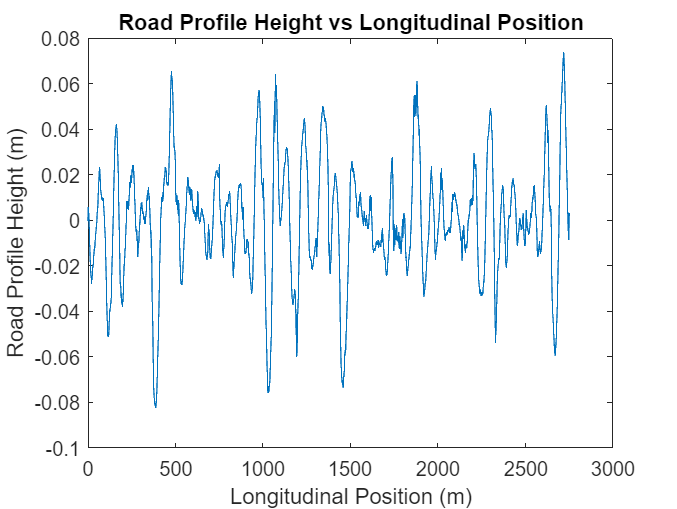

load road_profile.mat

plot(x_road, z_road)
title("Road Profile Height vs Longitudinal Position")
xlabel("Longitudinal Position (m)")
ylabel("Road Profile Height (m)")

Simulate at vel = 20 m/s and vel = 40 m/s

vel = 20; % m/s
x_start = 0; % m
x_stop = 1500; % m

% so it doesn't break (create tf)
[num, den] = ss2tf(A, B, C, D);

% simulate at 20 m/s
out20 = sim('car_suspension.slx');

% simulat at 40 m/s
vel = 40; % m/s
out40 = sim('car_suspension.slx');

Graph Relative Deflection vs. Position & Acceleration vs. Position

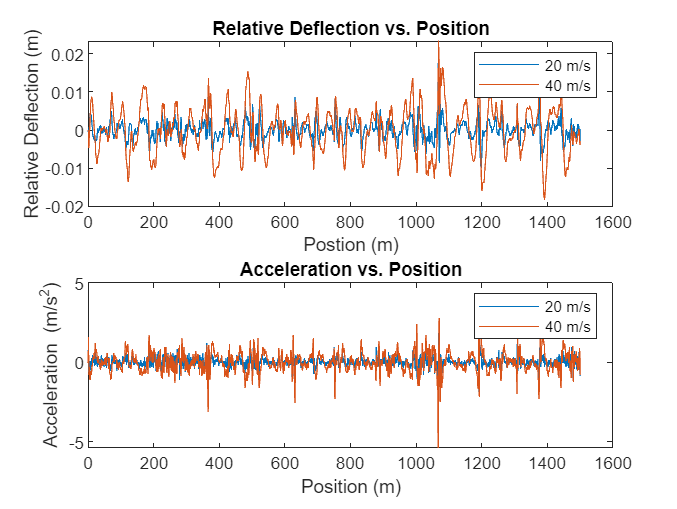

% Relative Deflection vs. Position Plot
subplot(2, 1, 1)
plot(out20.xpos.Data, out20.rel_pos.Data)
title("Relative Deflection vs. Position")
xlabel("Postion (m)")
ylabel("Relative Deflection (m)")

hold on
plot(out40.xpos.Data, out40.rel_pos.Data)
legend("20 m/s", "40 m/s")
hold off

% Acceleration vs. Position Plot
subplot(2, 1, 2)
plot(out20.xpos.Data, out20.accel.Data)
title("Acceleration vs. Position")
xlabel("Position (m)")
ylabel("Acceleration (m/s^2)")

hold on
plot(out40.xpos.Data, out40.accel.Data)
legend("20 m/s", "40 m/s")
hold off

Root Mean Squared

vel = 40; % m/s

% run the simulation at 100m intervals
for i = 1:1:27
    x_start = (i-1) * 100; % m
    x_stop = i * 100; % m
    out_rms = sim('car_suspension.slx');
    accel_rms(i) = rms(out_rms.accel.Data); % rms the accleration
end

Plot Bar Graph

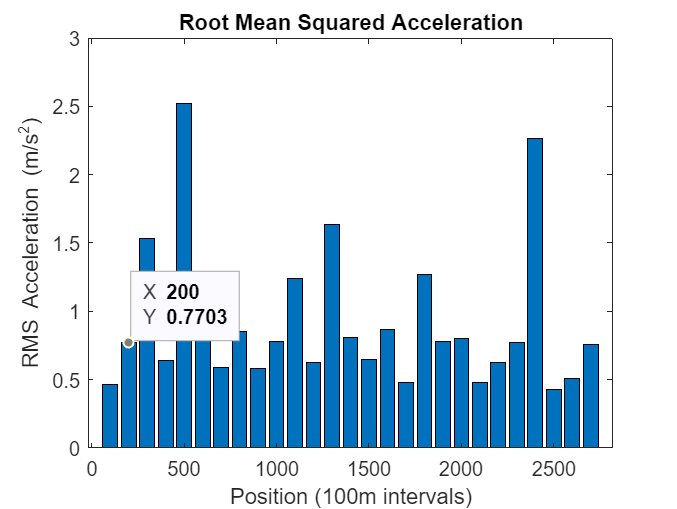

bar_pos = 100:100:2700; % x axis label

bar(bar_pos, accel_rms)
title("Root Mean Squared Acceleration")
xlabel("Position (100m intervals)")
ylabel("RMS Acceleration (m/s^2)")

Transfer Function Model

[num, den] = ss2tf(A, B, C, D); %tf 

vel = 40; % m/s
x_start = 0; % m
x_stop = 1500; % m

% initial conditions
x1 = 0.01; 
x1_dot = 0.1;
x2 = 0.04; 
x2_dot = 0.02;
init_c = [x1; x1_dot; x2; x2_dot];

out_tf = sim('car_suspension.slx');

Graph Acceleration vs. Position

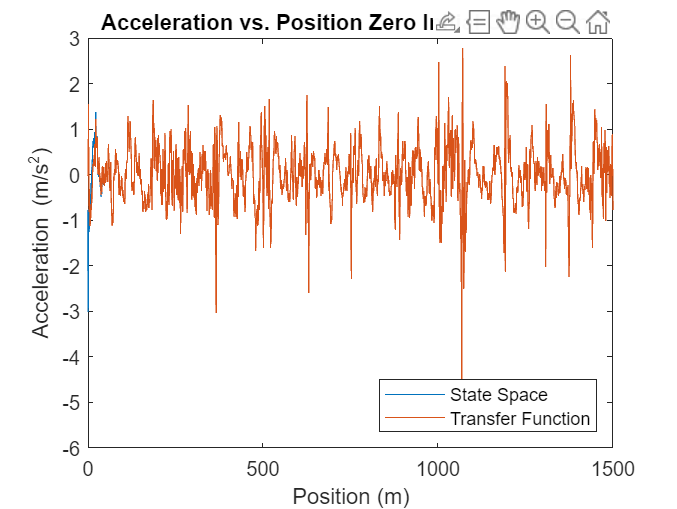

plot(out_tf.xpos.Data, out_tf.accel.Data)
title("Acceleration vs. Position Non-Zero Initial Conditions")
xlabel("Position (m)")
ylabel("Acceleration (m/s^2)")

hold on
plot(out_tf.xpos.Data, out_tf.accel_tf.Data(:,3))
legend("State Space", "Transfer Function", "Location", "southeast")
hold off

Graph Acceleration vs. Position (Zoomed)

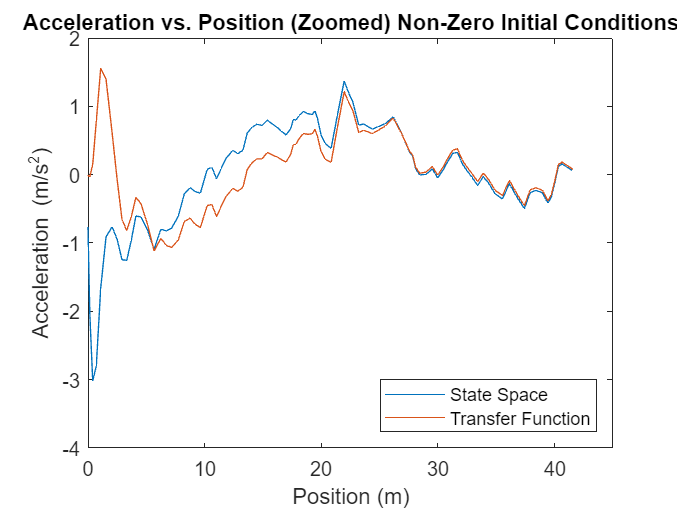

figure
plot(out_tf.xpos.Data(1:100), out_tf.accel.Data(1:100))
axis([0 45 -4 2])
title("Acceleration vs. Position (Zoomed) Non-Zero Initial Conditions")
xlabel("Position (m)")
ylabel("Acceleration (m/s^2)")

hold on
plot(out_tf.xpos.Data(1:100), out_tf.accel_tf.Data(1:100,3))
legend("State Space", "Transfer Function", "Location", "southeast")
hold off